clear all

%Constantes
m = 15 

m = 15

cd = 0.47

cd = 0.4700

A = 0.8

A = 0.8000

dt = 0.01

dt = 0.0100

step = 0.001:0.001:25

step =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


g = 9.81

g = 9.8100



%Functions%
p = @(y) y*-7.8*10^(-5)+1.225

p = function_handle with value:
    @(y)y*-7.8*10^(-5)+1.225


k = @(y) cd*A*p(y)

k = function_handle with value:
    @(y)cd*A*p(y)


angle = @(vx, vy) atan2(vy,vx)

angle = function_handle with value:
    @(vx,vy)atan2(vy,vx)


getay = @(y, vx, vy, v) ( -k(y)*v^2*sin(angle(vx,vy)) / m - g )

getay = function_handle with value:
    @(y,vx,vy,v)(-k(y)*v^2*sin(angle(vx,vy))/m-g)


getax = @(y, vx, vy, v) (-k(y)*v^2*cos(angle(vx,vy))) / m

getax = function_handle with value:
    @(y,vx,vy,v)(-k(y)*v^2*cos(angle(vx,vy)))/m


getvy = @(pvy, dt, ay) pvy+ay*dt

getvy = function_handle with value:
    @(pvy,dt,ay)pvy+ay*dt


getvx = @(pvx, dt, ax) pvx+ax*dt

getvx = function_handle with value:
    @(pvx,dt,ax)pvx+ax*dt


getv = @(vx, vy) sqrt(vx^2 + vy^2)

getv = function_handle with value:
    @(vx,vy)sqrt(vx^2+vy^2)


getx = @(px, dt, vx) px+vx*dt

getx = function_handle with value:
    @(px,dt,vx)px+vx*dt


gety = @(py, dt, vy) py+vy*dt

gety = function_handle with value:
    @(py,dt,vy)py+vy*dt



%Constantes no tan constantes (input)
% v = zeros(1, length(step))
v(1) = 35

v = 35

y(1) = 10

y = 10



%Variables
% ang = zeros(1, length(step))
ang(1) = deg2rad(55)

ang = 0.9599



% vx = zeros(1, length(step))
vx(1) = v(1)*cos(ang(1))

vx = 20.0752

% vy = zeros(1, length(step))
vy(1) = v(1)*sin(ang(1))

vy = 28.6703

x(1) = 0

x = 0


% ax = zeros(1, length(step))
ax(1) = getax(y(1), vx(1), vy(1), v(1))

ax = -21.5617


% ay = zeros(1, length(step))
ay(1) = getay(y(1), vx(1), vy(1), v(1))

ay = -40.6033

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current pl

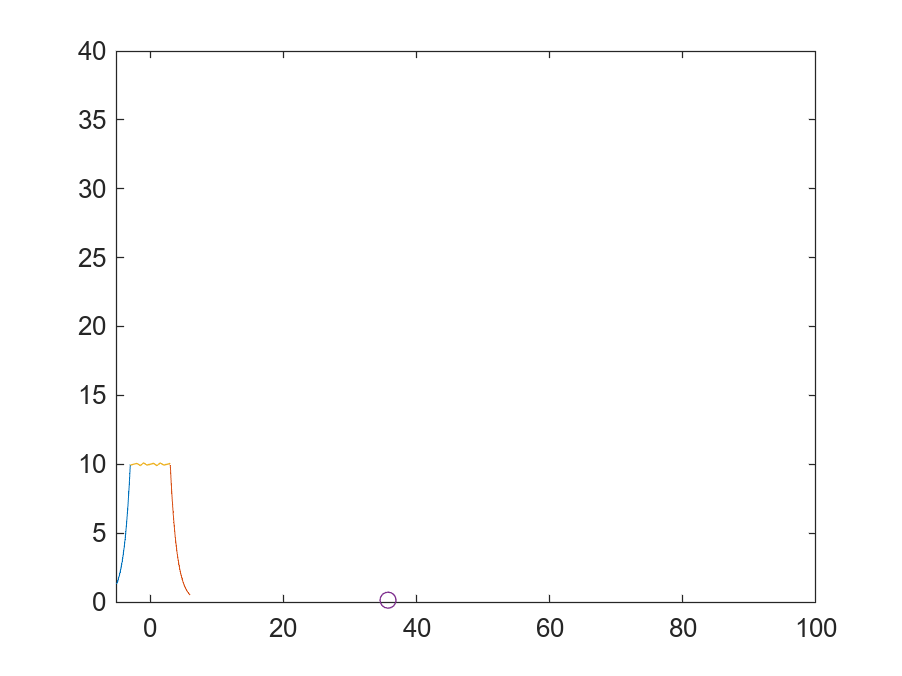


%Volcan plot



% ax(2) = getax(y(2-1), vx(2-1), vy(2-1), v(2-1))




for i=2:1:length(step)
    ax(i) = getax(y(i-1), vx(i-1), vy(i-1), v(i-1));
    ay(i) = getay(y(i-1), vx(i-1), vy(i-1), v(i-1));
    vx(i) = getvx(vx(i-1), dt, ax(i));
    vy(i) = getvy(vy(i-1), dt, ay(i));
    ang(i) = angle(vx(i), vy(i));
    x(i) = getx(x(i-1), dt, vx(i));
    y(i) = gety(y(i-1), dt, vy(i));
    v(i) = getv(vx(i), vy(i));

    if y(i) < 0
        break
    end
    
    t=-3:0.01:0;
    plot(t-3, exp(t)*y(1))
    hold
    plot(-t+3,exp(t)*y(1))
    plot(-3:0.5:3,(0.1*sin(5*(-3:0.5:3))+y(1)))
    plot(x(i), y(i), 'O') 
    axis([-5 100 0 40])
    drawnow limitrate
    hold off

end


% plot(x, y);






